# Initialization

clear
close all
clc
Param

# Map Generation

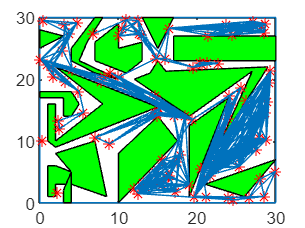

% number of nodes 
ns=100;
map=map_definition();
% 
% generate random nodes
[map, nodelocation]= generate_node(map,ns);
% create undirected graph and its edges
[undirectedGraph,unedges]=generate_undirected_graph(map,nodelocation);

# Start/End Point Def

% define start and end point of simulation
startp=[5, 29];
endp=[29, 20];

# Node Generation

% add start and end location as a new 2 nodes in undirected map.
% n+1 th node is start point, n+2th node is end point
[extungraph,exnodelocation,exunedges]=addstartendpoint2ungraph(map,undirectedGraph,nodelocation,unedges,startp,endp);
exundnodIndex=[1:ns+2];
snodeund=ns+1; 
enodeund=ns+2;

# Optimal Path Calc 

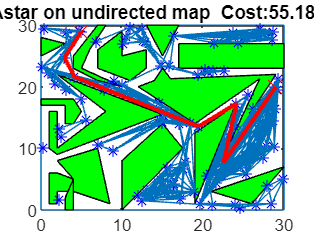

% optimal path with dijkstra on un-directional map
[Route, Cost] = dijkstra(extungraph,exnodelocation,snodeund);
rt=Route{enodeund};

dijkstra_route=exnodelocation(rt,:);
cost_dij=pathcost(dijkstra_route);
drawRoute('dijkstra on undirected map',snodeund,enodeund,exnodelocation,exundnodIndex,exunedges,rt,cost_dij);

% optimal path with astar on un-directional map
[Route] = astar(extungraph,exnodelocation,snodeund,enodeund);
astar_route=exnodelocation(Route,:);
cost_astar=pathcost(astar_route);
drawRoute('Astar on undirected map',snodeund,enodeund,exnodelocation,exundnodIndex,exunedges,Route,cost_astar);


% optimal path with dynamic programming on un-directional map
[parent, Route]=dynamicpathplanning(extungraph,exnodelocation,exundnodIndex,snodeund,enodeund);
dpundirected_route=exnodelocation(Route,:);
cost_dyn=pathcost(dpundirected_route);
drawRoute('Dynamic Programming on undirected map',snodeund,enodeund,exnodelocation,exundnodIndex,exunedges,Route,cost_dyn);


% Optimal Output
min_cost = min([cost_dij, cost_dyn, cost_astar])

min_cost = 55.1844

# Motion Verification

% TimePeriod = 1; 
% [Route2Simu, num_node] = Target2Signal(astar_route, TimePeriod);
% Simu_X = [Route2Simu(:, 1), Route2Simu(:, 2)]; 
% Simu_Y = [Route2Simu(:, 1), Route2Simu(:, 3)]; 
% Simout = sim('MotionGeneration.slx', (num_node-1)*TimePeriod); 